# Regression for parameter identification

We run the simulation in identificationV1.slx and we make a regression on the noisy States.

data = out.noisyStates.Data

data =     0.0252    0.0252    0.0252    0.0252    0.0252
    0.0252    0.0252    0.0252    0.0252    0.0250
    0.0252    0.0252    0.0252    0.0252    0.0240
    0.0252    0.0252    0.0252    0.0252    0.0190
    0.0252    0.0252    0.0252    0.0252   -0.0061
    0.0252    0.0252    0.0252    0.0257   -0.1313
    0.0252    0.0252    0.0252    0.0377   -0.7498
    0.0252    0.0252    0.0250    0.0737   -1.4876
    0.0252    0.0252    0.0248    0.1326   -2.2059
    0.0252    0.0252    0.0245    0.2137   -2.9046


time = out.timeVar.Data

time =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0004


load = out.loadTorque.Data

load =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



$$\begin{array}{l}
J\dot{\omega} =\Gamma_e -\Gamma_l +f_v \omega \\
\leftrightarrow 0=\Gamma_e -\Gamma_l +f_v \int \omega \;\mathrm{dt}-J\omega \;\mathrm{discrétisation},\;\mathrm{méthode}\;\mathrm{des}\;\mathrm{trapèzes}\\
\leftrightarrow {0=\;\Gamma }_{e,k} -\Gamma_{l,k} +f_v \left(t_k -t_{k-1} \right)\frac{1}{2}\left(\omega {\;}_k +\omega {\;}_{k+1} \right)-J\omega_k \;\mathrm{définition}\;\Gamma_e \\
\leftrightarrow 0=\frac{f_v }{J}\left(t_k -t_{k-1} \right)+\frac{p\;L_m }{J\;L_r }\left(i_{\beta } \phi_{\alpha } -i_{\beta } \phi_{\alpha } \right)-\frac{1}{J}\Gamma_l 
\end{array}$$



%mechanical equation regression
omega = data(:,1)

omega =     0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252


ibeta = data(:,5)

ibeta =     0.0252
    0.0250
    0.0240
    0.0190
   -0.0061
   -0.1313
   -0.7498
   -1.4876
   -2.2059
   -2.9046


ialpha = data(:,4)

ialpha =     0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0257
    0.0377
    0.0737
    0.1326
    0.2137


phibeta = data(:,3)

phibeta =     0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0250
    0.0248
    0.0245


phialpha = data(:,2)

phialpha =     0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252


ys = omega(2:end)

ys =     0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252
    0.0252


%trapèzes
%x1s = 0.5*(time(2:end)-time(1:end-1)).*(omega(2:end)+omega(1:end-1))
%rectangles
x1s = time(2:end)-time(1:end-1).*omega(2:end)

x1s =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005


x2s = time(2:end)-time(1:end-1).*(ibeta(2:end).*phialpha(2:end)-ialpha(2:end).*phibeta(2:end))

x2s =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005


x3s = time(2:end)-time(1:end-1).*(load(2:end)) %load torque

x3s =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005


Xs = [x1s,x2s,x3s]

Xs =     0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0001
    0.0002    0.0002    0.0002
    0.0003    0.0003    0.0003
    0.0004    0.0004    0.0004
    0.0005    0.0005    0.0005


thetas = pinv(Xs)*ys

thetas =    -0.4192
  -11.0309
   99.8970


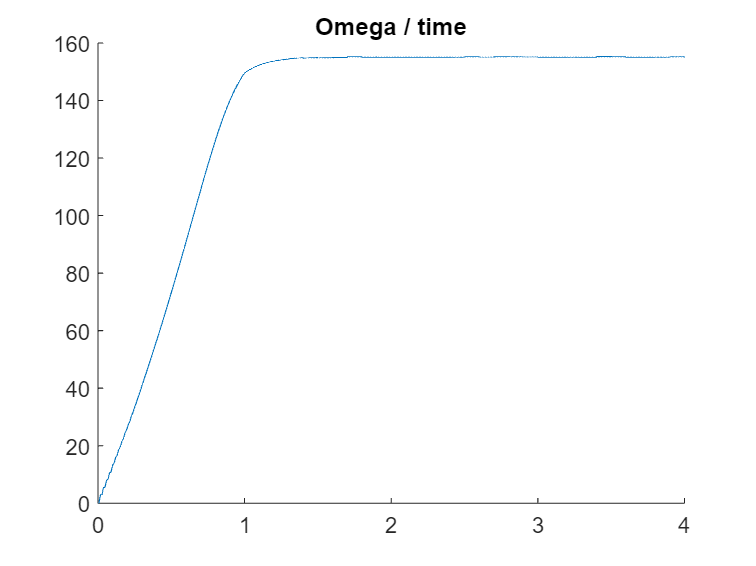


figure;
title("Omega / time")
hold on;
plot(time(2:end),ys)
hold off;


%analytical values
disp([fv/J,thetas(1)])

    0.1310   -0.4192



disp([p*L_m/(J*L_r),thetas(2)])

   89.8367  -11.0309



disp([-1/J,thetas(3)])

  -34.4828   99.8970

